# Count number of sessions in Wandell lab projects

Illustrates searching the Flywheel database from Matlab for session information 

## Authorization

Open the scitran object, here we name the instance 'vistalab'. This uses the URL of your Flywheel instance and the API key. 

st = scitran('stanfordlabs')   % Create a scitran object

st =   scitran with properties:

         url: 'https://stanfordlabs.flywheel.io'
    instance: 'stanfordlabs'
          fw: [1×1 flywheel.Flywheel]


## Search for all projects and print their labels

allProjects = st.search('project');
projectLabels = stPrint(allProjects,'project','label');


 project label
-----------------------------
	1 - SVIP Released Data (SIEMENS) 
	2 - Autism Phenome 
	3 - ENGAGE 
	4 - Weston Havens 
	5 - SVIP: Unreleased Data 
	6 - UMN 
	7 - HCP_preproc 
	8 - VWFA FOV 
	9 - Reading Longitude: DWI 
	10 - SVIP (Philips) 
	11 - PRATIK 
	12 - BCBL_ILLITERATES 
	13 - CoRR 
	14 - ADNI: T1 
	15 - DES-fMRI 
	16 - ALDIT 
	17 - Graphics assets 
	18 - ADNI: DWI (MCI) 
	19 - ADNI: DWI (AD) 
	20 - HCP 
	21 - showdes 
	22 - VWFA FOV Hebrew 
	23 - ADNI: DWI (Normal Controls) 
	24 - fastrest 
	25 - Templates Adult 
	26 - VWFA 
	27 - Rorie PLoS One 2010 
	28 - Brain Beats 
	29 - Dental 
	30 - SOC ECoG (Hermes) 
	31 - retinotopy 
	32 - Peds: Reading - Feldman 
	33 - MS: JWDay 
	34 - ds001 
	35 - Albinism: Control 
	36 - Oral Eye 
	37 - Renderings 
	38 - TBI: NeuroCor 
	39 - Templates Neonatal 
	40 - DEMO 
	41 - Templates Pediatric 
	42 - Templates Macaque 
	43 - Velscope 
	44 - Kiani Current Biology 2014 
	45 - EJ Apricot 
	46 - Recon Test 
	47 - ENGAGE-AFQ 
	48 - P

nProjects = numel(allProjects);

% Another way to do it
% allProjects = st.list('project','all');
% projectLabels = stPrint(allProjects,'label','') 

## Count the number of sessions in each project

numSessions = stProjectGet(st, allProjects, 'numsessions');

## Histogram of number of sessions across projects

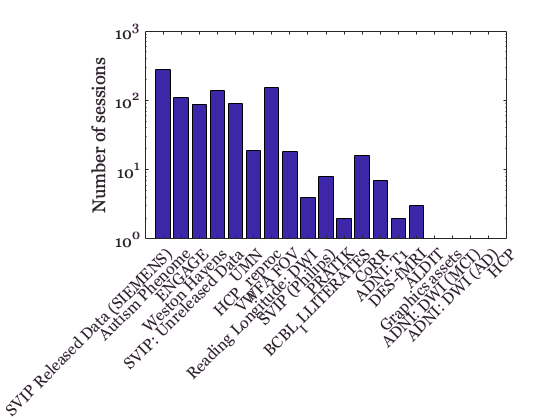

theseProjects = 1:3:nProjects;
bar(numSessions(theseProjects));

% Only plot some of them
set(gca,'XTick', 1:nProjects, ...
    'XTickLabels', projectLabels);
xtickangle(45);
ylabel('Number of sessions');
set(gca,'yscale','log')